clear;
clf;
load("Iin.mat");
load("Iout.mat");
load("Vin");
[first, last, mmax_log, bmax_log, Nmax]=linefit(log(Iin), log(Iout), 5e-4)

first = 1

last = 50

mmax_log = 0.9972

bmax_log = -0.0084

Nmax = 50

[first, last, mmax, bmax, Nmax]=linefit(Iin, Iout, 5e-4)

first = 1

last = 50

mmax = 1.0198

bmax = 1.6107e-07

Nmax = 50

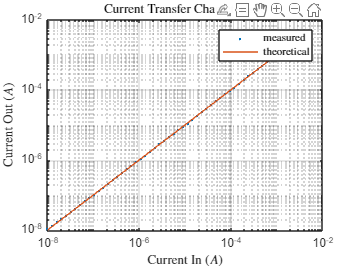

loglog(Iin, Iout,'.')
hold on;
% loglog(Iin, exp(bmax_log)*(Iin.^mmax_log))
% loglog(Iin, Iin*mmax + bmax)
loglog(Iin, Iin*mmax)
title("Current Transfer Characteristic","Interpreter","latex");
xlabel("Current In ($A$)", "Interpreter","latex");
ylabel("Current Out ($A$)", "Interpreter", "latex");
legend("measured", "theoretical", "Interpreter", "latex")
grid on;
hold off;